clc;
clearvars;

**Input variables:**

% Variable                              % Explanation                             Unit
prompt = "What is the mass flow? ";
W = input(prompt)
% W = 100;                                % Mass flow                               (kg/s)
R = 287.05;                             % Gas constant                            (J/kgK)
IntakeP_loss = 0;                       % Intake pressure loss                    (%)
ExhaustP_loss = 0;                      % Exhaust pressure loss                   (kPa)
JetpipeP_loss = 0;                      % Jet pipe pressure loss                  (%)
PPS = 9;                                % Pressure to static pressure ratio       (-)            Derived from C3.10
CD = 1;                                 % Coefficient of discharge                (%)
CX = 1;                                 % Coefficient of thrust                   (%)
Mech_Eff = 0.86;                        % Mechanical efficiency                   (%)

**Compressor:**

prompt = "What is the gamma cold? ";
y_c = input(prompt)
% y_c = 1.4;                              % Heat capacity ratio compressor          (-)
prompt = "What is the compressor isentropic efficiency? ";
ETA2 = input(prompt)
% ETA2 = 0.9;                             % Compressor isentropic efficiency        (%)
ETAP2 = 0;                              % Compressor polytopic efficiency         (%)
prompt = "What is the compressor CP in kJ/kg? ";
CP_compressor = input(prompt)
% CP_compressor = 1.000;                  % Specific heat compressor                (kJ/kg)
prompt = "What is the compressor Pressure Ratio? ";
P3Q2 = input(prompt)
% P3Q2 = 8;                               % Pressure ratio compressor               (-)
CompressorP_loss = 0;                   % Compressor pressure loss                (%

**Combustor:**

prompt = "What is the combustor pressure loss? ";
CombustionP_loss = input(prompt)
% CombustionP_loss = 0.05;                % Combustion pressure loss                (kPa)
ETA34 = 0.999;                          % Combustion efficiency                   (%)

**Turbine:**

prompt = "What is the gamma hot? ";
y_t = input(prompt)
% y_t = 1.33;                             % Heat caapcity ratio turbine             (-)
prompt = "What is the turbine isentropic efficiency? ";
TurbineIsent_Eff = input(prompt)
% TurbineIsent_Eff = 0.86;                % Turbine isentropic efficiency           (%)
TurbinePoly_Eff = 0;                    % Turbine polytropical eff.               (%)
prompt = "What is the turbine CP in kJ/kg? ";
CP_turbine = input(prompt)
% CP_turbine = 1.150;                     % Specific heat turbine                   (kJ/kg)

**Pressures:**

P1 = 101;                               % Pressure at intake                      (kPa)
PAMB = 101;                             % Ambient pressure                        (kPa)

**Temperatures:**

TAMB = 288;                             % Ambient temperature                     (K)
T4 = 1800;                              % Temperature after combustion            (K)
T41 = 1800;                             % Stator outlet temperature               (K)

**Bleed:**

Bleed1 = 0;                             % Bleed air from compressor to outlet     (%)
Bleed2 = 0;                             % Bleed air from compressor to LPT        (%)
Bleed3 = 0;                             % Bleed air from compressor to HPT        (%)
Bleed4 = 0;                             % Bleed air to first LPT nozzle           (%)
Bleed5 = 0;                             % Bleed air to second LPT nozzle          (%)

**Fuel:**

prompt = "What is the fuel calorific value in J/kg? ";
LHV = input(prompt)
% LHV = 43000;                            % Calorific value fuel                    (J/kg)

**Stations: **

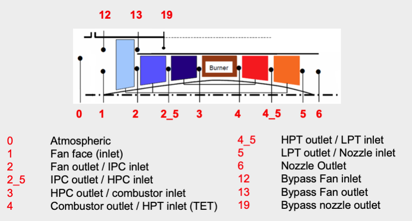

**Intake calculations:**

T1 = TAMB
T2 = T1
P2 = P1 * (1 - IntakeP_loss)                                       

**Compressor calculations: **

% ETA2 = (P3Q2^((y_c-1)/y_c)-1)/(P3Q2^((y_c-1)/(y_c*ETAP2))-1);     % Converts polytropic to isentropic                                
T3 = T2/ETA2 * (P3Q2^((y_c-1)/y_c)-1) + T2                          % T2 divided by Combustion eff. formula F5.1.4 states that it should be divided by ETA2
P3 = P3Q2 * P2;
W3 = W;                                                             
Tbleed = (T3 + T1)/2;
PW2 = W * (CP_compressor) * (T3 - T1)                               % No Tbleed

**Compressor exit diffuser calculations: **

T31 = T3;
P31 = P3 * (1- CompressorP_loss);
W31 = W3 - (W * Bleed2) - (W * Bleed3);

**Combustor and SOT station calculations: **

P41 = P31 * (1 - CombustionP_loss)
FAR1 = 0.10118 + 2.00376E-05 * (700- T3);
FAR2 = 3.7078E-03 - 5.2368E-06 * (700 - T3) - 5.2632E-06 * T41;
FAR3 = 8.889E-08 * abs(T41 - 950);
FAR = (FAR1 - sqrt(FAR1^2 + FAR2) - FAR3)/ETA34;

DT = T4 - T3;
DH = DT * W * CP_turbine;
WF = DH/LHV                                                   % WF = FAR * (W31 + W * 0.075) is not corresponding

W41 = W31 + W * (Bleed3) + WF;
W4 = W31 + WF;
T4 = ((W41 * CP_turbine * T41)-(Bleed3 * 100 *(CP_compressor) * T3))/(W4 * CP_turbine)
P4 = P41;
W415 = W41 + W * Bleed4;
T415 = (W41 * CP_turbine * T41 + Bleed4 * 100 * (CP_compressor)* T3)/(W415 * CP_turbine);
P415 = P41;

**Turbine calculations:**

P5 = PAMB/(1-ExhaustP_loss);
P416 = P5;
P415Q416 = P415/P5;
E415 = (1 - P415Q416^(- ((y_t-1)/y_t) * TurbineIsent_Eff))/(1 - P415Q416^(-(y_t-1)/y_t));
T416 = E415 * T415 * (1 - P415Q416^(-((y_t-1)/y_t)));
PW415 = W415 * CP_turbine * (T415 - T416);                
WRTP4 = W4 * sqrt(T4)/P4;
WRTP41 = W41 * sqrt(T41)/P4;

**Cooling air return of downstream caluclations:**

W5 = W415 + W * Bleed1 + W * Bleed5;
T5 = T4 - (PW2/(W4 * CP_turbine))

**Exhaust calculations: **

T9 = T5
P9 = P4 * (1 - ((1 - (T5/T4))/TurbineIsent_Eff))^4                 % P9 = ((1+(y_t-1)/2 * ExhaustP_loss^2)^(4)) * PAMB;
Q = 1000 * sqrt( 2 * y_t/((y_t-1) * R) * (PPS)^(-2/y_t) * (1 - (PPS)^ ((1 - y_t)/y_t)));

**Propelling nozzle calculations:**

T7 = T5;                                                           % P7 = P5 * (1 - JetpipeP_loss)
P7QN = P9 / PAMB;
PSN = P9 / PPS;                                                    % Static pressure nozzle
TSN = T5/(1+(y_t - 1)/(2 * 1^2));
VN = 1 * sqrt(y_t * R * TSN)                                       % Nett velocity
W7 = W5;                                             
ANeffective = (W7 * sqrt(T5))/(Q * P9);
ANgeometric = ANeffective/CD;
FG = W7 * VN + ANeffective * (PSN - PAMB) * 1000;                  % Gross thrust     PAMB at 9M

**Final calculations:**

V1 = sqrt(y_t * R * TSN)                                % Velocity
FD = 100 * V1;                                          % Momentum drag
FN = FG * CX - FD;                                      % Net thrust
SFN = FN/100                                            % Specific thrust
PW = PW415 - PW2/Mech_Eff                               % Output power
SFC = (WF/PW) * 10^6                                    % SFC = WF * 3600/FN not corresponding                   
SPW = PW/W                                              % Specific power 
ETATH = 100 * 3600/(SFC * LHV)                          % Thermal efficiency